# Joint Probabilistic Data Association Filter

This script applies a JPDA Filter to various examples. Some with simulated data, some with real-life applications such as estimation of traffic participants.

## Parameters

The following parameters have to be set for the JPDA Filter. They depend on the problem at hand. For this case, it is assumed that all targets will share the same dynamical model. The dynamical model is of the form:

x[k+1] = F*x[k] + G*u[k] + w[k]

z[k] = H*x[k] + v[k]

Here w is process noise with variance R and v is measurement noise with variance Q. Furthermore, in the measurement model it is assumed that there is a probability P_D that a target is detected, and a probability of P_FA of a false alarm measurement being made. In the case of a false alarm, the measurement is uniformly distributed over the complete map.

clear, clc

global F            % F matrix of dynamical model
global G            % G matrix of dynamical model
global H            % H matrix of measurement model
global R            % Covariance matrix of motion model | dimStates X dimStates
global Q            % Covariance matrix of measurement model | dimStates X dimStates
global tau          % Number of targets
global P_D          % Probability of a detection
global P_FA         % Probability of a false alarm
global map_size     % size for the map, centered around the origin | scalar

## 1D Random Walk Simulation

### Initialise

First we will define the dynamical model, measurement model, and the JPDA Filter parameters. Also the initial estimates and ground truth have to be set for each target.

% Number of targets
tau = 2;

% Simulation duration
delta_t = 0.1;      % [s] Time between simulation steps
end_time = 1;     % [s] Duration of simulation
n_timesteps = end_time/delta_t + 1;

% Define dynamical model
n_states = 1;              % Number of states of the dynamics model.
n_inp    = 1;              % Number of control inputs.
n_meas   = 1;              % Number of states of a measurement.
F = eye(n_states);
G = ones(n_states, n_inp);
H = eye(n_meas, n_states);

% Set values for JPDA parameters
R = 0.02*eye(n_states);
Q = 0.02*eye(n_meas);
P_D = 0.8;
P_FA = 0.5;

% Set the bounds of the map
map_size = 6;

% Initialise arrays to store each timestep for plotting
ground_truth = zeros(n_states,tau,n_timesteps);
mu = zeros(n_states,tau,n_timesteps);
sigma = zeros(n_states,n_states,tau,n_timesteps);
mu_gnn = zeros(n_states,tau,n_timesteps);
sigma_gnn = zeros(n_states,n_states,tau,n_timesteps);
% Cell arrays can have variable lengths for each timestep
z = cell(n_timesteps,1); 
association_ground_truth = cell(n_timesteps,1);

% Set initial estimate of target states
mu(:,:,1) = [1, 2];
mu_gnn(:,:,1) = mu(:,:,1);

% Set initial estimate of covariances. Increase to start with less certainty
sigma(:,:,:,1) = repmat(1*R,[1,1,tau]);
sigma_gnn(:,:,:,1) = sigma(:,:,:,1);

% Sample a ground truth for each target
for t = 1:tau
    ground_truth(:,t,1) = mvnrnd(mu(:,t,1),sigma(:,:,t,1));
end

### Run

Here we run the simulation. For each time-step, we simulate a ground truth and measurements, then the iterate() function performs an iteration of the JPDA filter. Since it is a random-walk, we don't have any inputs.

for timestep = 2:n_timesteps
    % Retrieve u (0 for a random walk)
    u = zeros(n_inp,tau);
    
    % Simulate dynamical model
    [ground_truth(:,:,timestep)] = simulate_dynamics(ground_truth(:,:,timestep-1), u);

    % Simulate measurements
    [z{timestep}, association_ground_truth{timestep}] = simulate_measurements(ground_truth(:,:,timestep));
    
    % Do an iteration of JPDA Filter
    [mu(:,:,timestep), sigma(:,:,:,timestep)] = iterate(mu(:,:,timestep-1), sigma(:,:,:,timestep-1), u, z{timestep});

    % Do an iteration of GNN Filter
    [mu_gnn(:,:,timestep), sigma_gnn(:,:,:,timestep)] = gnn_iterate(mu_gnn(:,:,timestep-1), sigma_gnn(:,:,:,timestep-1), u, z{timestep});
end

### Visualize results

Visualization for a 1D Random walk. Since it is only 1D, we can plot the states overtime.

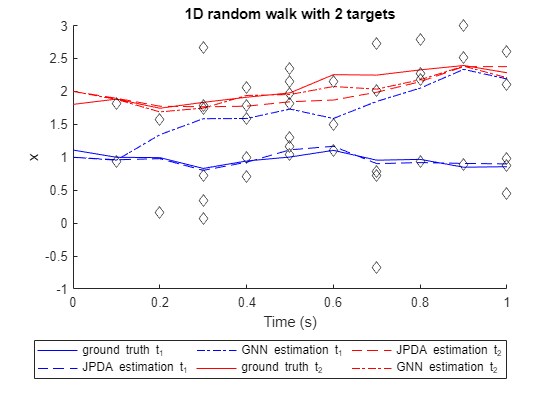

timesteps = 0:delta_t:end_time;

figure(1), clf(1), hold on
legendstrings = [];
colororder = ["blue", "red", "green"];
for t = 1:tau
    plot(timesteps,squeeze(ground_truth(1,t,:)), 'Color', colororder(t))
    plot(timesteps,squeeze(mu(1,t,:)),'--', 'Color', colororder(t))
    plot(timesteps,squeeze(mu_gnn(1,t,:)),'-.', 'Color', colororder(t))
    legendstrings = [legendstrings, "ground truth t_" + num2str(t), "JPDA estimation t_" + num2str(t), "GNN estimation t_" + num2str(t)];
end
for k = 1:n_timesteps
    if ~isempty(z{k})
        scatter((k-1)*delta_t, z{k},'d','MarkerEdgeColor','black')
    end
end
xlabel("Time (s)");
ylabel("x");
title("1D random walk with " + num2str(tau) + " targets");
legend(legendstrings,'Location','southoutside','NumColumns',3)
hold off

## Compare mean square errors

When we run this simulation multiple times, we can get a good estimation of the mean square errors of both the JPDA and the GNN algorithm

n_reps = 1000;
[jpda_mse, gnn_mse] = compute_MSE(n_reps);
disp("JPDA Mean Square Error: " + jpda_mse)

JPDA Mean Square Error: 0.084831


disp("GNN Mean Square Error: " + gnn_mse)

GNN Mean Square Error: 0.16089


## 2D Trajectories Simulation

### Initialise

We will now simulate some trajectories in 2D and see how the JPDA does the data association

% Number of targets
tau = 3;

% Simulation duration
delta_t = 0.1;      % [s] Time between simulation steps
end_time = 10;      % [s] Duration of simulation
n_timesteps = end_time/delta_t + 1;

% Define dynamical model
n_states = 2;              % Number of states of the dynamics model.
n_inp    = 2;              % Number of control inputs.
n_meas   = 2;              % Number of states of a measurement.
F = eye(n_states);
G = delta_t*eye(n_states, n_inp);
H = eye(n_meas, n_states);

% Set values for JPDA parameters
R = 0.005*eye(n_states);
Q = 0.02*eye(n_meas);
P_D = 0.8;
P_FA = 0.5;

% Set the bounds of the map
map_size = 6;

% Initialise arrays to store each timestep for plotting
ground_truth = zeros(n_states,tau,n_timesteps);
mu = zeros(n_states,tau,n_timesteps);
sigma = zeros(n_states,n_states,tau,n_timesteps);
% Cell arrays can have variable lengths for each timestep
z = cell(n_timesteps,1); 
association_ground_truth = cell(n_timesteps,1);
beta = cell(n_timesteps,1);

% Set initial estimate of target states
mu(:,:,1) = map_size*(rand(n_states, tau)-0.5);
mu(:,:,1) = [-5, 0, -3; 0, -5, 5];

% Set initial estimate of covariances. Increase to start with less certainty
sigma(:,:,:,1) = repmat(1*R,[1,1,tau]);

% Sample a ground truth for each target
for t = 1:tau
    ground_truth(:,t,1) = mvnrnd(mu(:,t,1),sigma(:,:,t,1));
end


### Run

for timestep = 2:n_timesteps
    % Retrieve u (0 for a random walk)
    u = [1, 0, 0.6; 0, 1, -0.7];
    
    % Simulate dynamical model
    [ground_truth(:,:,timestep)] = simulate_dynamics(ground_truth(:,:,timestep-1), u);

    % Simulate measurements
    [z{timestep}, association_ground_truth{timestep}] = simulate_measurements(ground_truth(:,:,timestep));
    
    % Do an iteration of JPDA Filter
    [mu(:,:,timestep), sigma(:,:,:,timestep), beta{timestep}] = iterate(mu(:,:,timestep-1), sigma(:,:,:,timestep-1), u, z{timestep});
end

### Visualise results

Since we now have 2D states, we can make a video of the ground truths and estimates. Furthermore, in this video we can include the estimation uncertainties, the association probabilities, and the measurements with their ground truth association. 

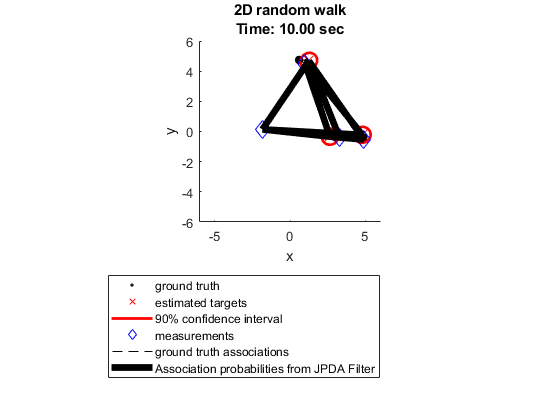

% Select what to include into the plotting
include_uncertainties = true;
include_association_probabilities = true;
include_measurements = true;
include_ground_truth_association = true;

% Initialise figure
figure(2), clf(2), hold on
title(sprintf('2D random walk\nTime: %0.2f sec', 0));
xlabel("x");
ylabel("y");
xlim([-map_size, map_size])
ylim([-map_size, map_size])
axis equal

% Plotting first iteration
% Plot ground truth
gt_plot = scatter(ground_truth(1,:,1), ground_truth(2,:,1),500,'.','black');
% Plot estimates
mu_plot = scatter(mu(1,:,1), mu(2,:,1),100,'x','red');
if include_uncertainties
    XData = zeros(100,tau);
    YData = zeros(100,tau);
    for t = 1:tau
        [XData(:,t), YData(:,t)] = plotErrorEllipse(mu(:,t,1), sigma(:,:,t,1),0.9);
    end
    sigma_plot = plot(XData,YData,'LineWidth',2,'Color',[1, 0, 0, 0.3]);
end
% Plot measurements (empty, first timestep has no measurements)
if include_measurements
    z_plot = scatter([], [],100,'d','blue');
end
% Plot ground truth associations (empty, first timestep has no measurements)
if include_ground_truth_association
    gt_associations_plot = plot(zeros(2,tau), zeros(2,tau), '--k', 'LineWidth', 0.5);
end
% Plot association probabilities (empty, first timestep has no measurements)
if include_association_probabilities
    % Initialised with a max of allocate*tau measurements, so it might break with bad luck
    allocate = 5;
    beta_plot = plot(zeros(2,allocate*tau*tau), zeros(2,allocate*tau*tau), '-k', 'LineWidth', 5);
end
% Set legend
legend([gt_plot, mu_plot, sigma_plot(1), z_plot, gt_associations_plot(1), beta_plot(1)],{'ground truth','estimated targets','90% confidence interval','measurements','ground truth associations','Association probabilities from JPDA Filter'},'Location','southoutside')


% Iterating through the time array
for timestep = 2:n_timesteps
    % Update title
    title(sprintf('2D random walk\nTime: %0.2f sec', delta_t*(timestep-1)));
    
    % Update ground truth
    set(gt_plot, 'XData', ground_truth(1,:,timestep));
    set(gt_plot, 'YData', ground_truth(2,:,timestep));
    % Update estimates
    set(mu_plot, 'XData', mu(1,:,timestep));
    set(mu_plot, 'YData', mu(2,:,timestep));
    if include_uncertainties
        XData = zeros(100,tau);
        YData = zeros(100,tau);
        for t = 1:tau
            [XData(:,t), YData(:,t)] = plotErrorEllipse(mu(:,t,timestep), sigma(:,:,t,timestep),0.9);
        end
        set(sigma_plot, {'XData'}, mat2cell(XData',ones(1,tau),100))
        set(sigma_plot, {'YData'}, mat2cell(YData',ones(1,tau),100))
    end
    % Update measurements
    if include_measurements
        set(z_plot, 'XData',z{timestep}(1,:));
        set(z_plot, 'YData',z{timestep}(2,:));
    end
    % Update ground truth associations
    if include_ground_truth_association
        XData = zeros(2,tau);
        YData = zeros(2,tau);
        % Remove clutter measurements, those have no truth association
        filtered = association_ground_truth{timestep} ~= 0;
        XData(:,1:sum(filtered)) = [z{timestep}(1,filtered);
                                    ground_truth(1,association_ground_truth{timestep}(filtered),timestep)];
        YData(:,1:sum(filtered)) = [z{timestep}(2,filtered);
                                    ground_truth(2,association_ground_truth{timestep}(filtered),timestep)];
        set(gt_associations_plot, {'XData'}, mat2cell(XData',ones(1,tau),2))
        set(gt_associations_plot, {'YData'}, mat2cell(YData',ones(1,tau),2))
    end
    % Update association probabilities
    if include_association_probabilities
        [n_targets, n_measurements] = size(beta{timestep});
        target_indices = repmat(1:n_targets,[1, n_measurements]);
        meas_indices = repelem(1:n_measurements,n_targets);
        
        XData = zeros(2,allocate*tau*tau);
        YData = zeros(2,allocate*tau*tau);
        color = zeros(allocate*tau*tau,4);
        XData(:,1:n_targets*n_measurements) = [mu(1,target_indices,timestep);
                                               z{timestep}(1,meas_indices)];
        YData(:,1:n_targets*n_measurements) = [mu(2,target_indices,timestep);
                                               z{timestep}(2,meas_indices)];

        opacity = reshape(beta{timestep},[],1);
        color(1:n_targets*n_measurements,4) = opacity;

        set(beta_plot, {'XData'}, mat2cell(XData',ones(1,allocate*tau*tau),2))
        set(beta_plot, {'YData'}, mat2cell(YData',ones(1,allocate*tau*tau),2))
        set(beta_plot, {'Color'}, mat2cell(color, ones(1,allocate*tau*tau),4))
    end
    
    % Reinforce map size
    xlim([-map_size, map_size])
    ylim([-map_size, map_size])

    drawnow
end
hold off

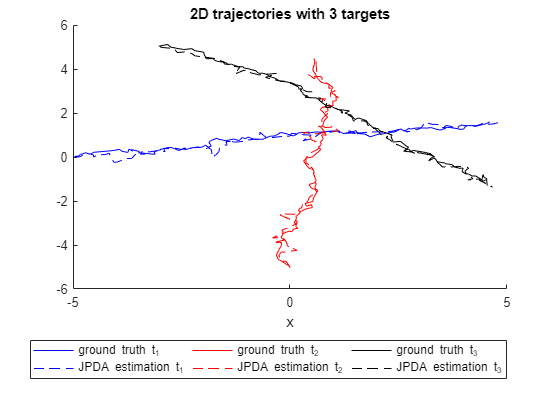

% In a new plot we can plot the overal results
figure(3), clf(3), hold on
legendstrings = [];
colororder = ["blue", "red", "black"];
for t = 1:tau
    plot(squeeze(ground_truth(1,t,:)), squeeze(ground_truth(2,t,:)), 'Color', colororder(t))
    plot(squeeze(mu(1,t,:)), squeeze(mu(2,t,:)), '--', 'Color', colororder(t))
    legendstrings = [legendstrings, "ground truth t_" + num2str(t), "JPDA estimation t_" + num2str(t)];
end
xlabel("x");
ylabel("");
title("2D trajectories with " + num2str(tau) + " targets");
legend(legendstrings,'Location','southoutside','NumColumns',3)
hold off

function [plotX, plotY] = plotErrorEllipse(mu, Sigma, p)
    % Helper function for plotting uncertainty bounds
    s = -2 * log(1 - p);
    [V, D] = eig(Sigma * s);
    t = linspace(0, 2 * pi);
    a = (V * sqrt(D)) * [cos(t(:))'; sin(t(:))'];

    plotX = a(1, :) + mu(1);
    plotY = a(2, :) + mu(2);
end